# Calculate smoke exposure

## Set up some parameters


years           = 2019;
start_mon       = 11;
end_mon         = 11;
start_date      = 1;
end_date        = 30;
backward_hours  = 120;
rundays         = datenum(years,end_mon,end_date) - datenum(years,start_mon,start_date) + 1;
receptors       = 11;

% leap year?
if(( rem(years,100)~= 0 && rem(years,4) == 0) || (rem(years,100) == 0 && rem(years,400) == 0))
    ndays = 366;
    ndays_mon = [31,29,31,30,31,30,31,31,30,31,30,31];
else
    ndays = 365;
    ndays_mon = [31,28,31,30,31,30,31,31,30,31,30,31];
end

% start/end dates
if start_mon == 1
    tt_indx1 = 1;
    tt_indx2 = ndays_mon(end_mon);
else
    tt_indx1 = sum(ndays_mon(1:start_mon-1))+1;
    tt_indx2 = sum(ndays_mon(1:end_mon));
end

% Southeastern Australia
% 1. Footscray; 2. Albury; 3. Florey; 4. Wollongong; 5. Prospect; 6. Newcastle; 
% 7. Mountain Creek; 8. Springwood; 9. Alphington; 10. Liverpool; 11. Wallsend; 
loc_str = {'144.8728027_-37.80487823','146.93986_-36.05182',...
           '149.043539_-35.220606','150.88733_-34.41706',...
           '150.91417_-33.79424','151.75965_-32.9312',...
           '153.1038_-26.6917','153.1356_-27.6125',...
           '145.0306_-37.7784','150.9058_-33.9328','151.6692_-32.8961'};
loc_lon = [144.8728027,146.93986,149.043539,150.88733,150.91417,151.75965,...
           153.1038,153.1356,145.0306,150.9058,151.6692];
loc_lat = [-37.80487823,-36.05182,-35.220606,-34.41706,...
           -33.79424,-32.9312,-26.6917,-27.6125,-37.7784,-33.9328,-32.8961];


## Step 1: Read the biomass burning emissions


disp('Step 1');

Step 1


location = 'C:\Users\fox\Desktop\demo_HEI\GFED\';
prefix = 'GFEDv4s_';
postfix = '.nc';
spc_name = {'BC','OC'};

dirfiles = dir([location,prefix,'*']);
filename1 = dirfiles.name;
lon_global_gfed = ncread([location,filename1],'lon');
lat_global_gfed = ncread([location,filename1],'lat');

% target emission unit: kg m^-^2 s^-^1
aemit_daily = zeros(length(lon_global_gfed),length(lat_global_gfed),ndays,2); % 1: BC; 2: OC

for ispc = 1:2
    for imon = 1:12
        if imon < 10
            filename = [location,prefix,num2str(years),'_0',num2str(imon),'_',char(spc_name(ispc)),postfix];
        else
            filename = [location,prefix,num2str(years),'_',num2str(imon),'_',char(spc_name(ispc)),postfix];
        end

        if imon == 1
            startday = 1;
            endday = sum(ndays_mon(imon));
        else
            startday = sum(ndays_mon(1:imon-1))+1;
            endday = sum(ndays_mon(1:imon));
        end

        disp(filename);
        aemit_daily(:,:,startday:endday,ispc) = ncread(filename,char(spc_name(ispc)));
    end
end

C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_01_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_02_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_03_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_04_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_05_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_06_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_07_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_08_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_09_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_10_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_11_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_12_BC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_01_OC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_02_OC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_03_OC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_04_OC.nc
C:\Users\fox\Desktop\demo_HEI\GFED\GFEDv4s_2019_05_OC.nc
C:\Users\fox\Desktop\demo_HEI\G


aemit_daily_4 = aemit_daily; % for scale emission random forest
lon_global = lon_global_gfed;
lat_global = lat_global_gfed;

filepath = 'C:\Users\fox\Desktop\demo_HEI\STILT_output\2019_se\';
diroutput = dir(fullfile(filepath,'*_foot.nc'));
filename = {diroutput.name};
filename_1 = char(filename(1));
lon = ncread([filepath,filename_1],'lon');
lat = ncread([filepath,filename_1],'lat');

% simulated region
lon_indx1 = find( abs(min(lon) - lon_global_gfed) == min( abs(min(lon) - lon_global_gfed) ));
lon_indx2 = find( abs(max(lon) - lon_global_gfed) == min( abs(max(lon) - lon_global_gfed) ));
lat_indx1 = find( abs(min(lat) - lat_global_gfed) == min( abs(min(lat) - lat_global_gfed) ));
lat_indx2 = find( abs(max(lat) - lat_global_gfed) == min( abs(max(lat) - lat_global_gfed) ));

gfed_var = aemit_daily(lon_indx1(1):lon_indx2(1),lat_indx1(1):lat_indx2(1),tt_indx1:tt_indx2,:);
lon_gfed_au = lon_global_gfed(lon_indx1(1):lon_indx2(1));
lat_gfed_au = lat_global_gfed(lat_indx1(1):lat_indx2(1));


## Step 2: Use estimated plume injection fractions from random forest to scale biomass burning emissions

disp('Step 2');

Step 2


clearvars gfed_all inheight_all pblh_all
load(['E:\work_for_wildfires\random_forest\predicted_injection_percentages_rf\new\predict_output_au_',num2str(years),'.mat']);
eval(['ratio_all','=','predict_output_au_',num2str(years),';']);

for ispc = 1:2
     gfed_var_new(:,:,:,ispc) = (1 - ratio_all(:,:,tt_indx1:tt_indx2)) .* gfed_var(:,:,:,ispc);
end
aemit_daily_4(lon_indx1(1):lon_indx2(1),lat_indx1(1):lat_indx2(1),tt_indx1:tt_indx2,:) = gfed_var_new;


## Step 3: Read and process the daily sentivity footprints

% STILT output files
disp('Step 3');

Step 3


filepath = ['C:\Users\fox\Desktop\demo_HEI\STILT_output\2019_se\'];
diroutput = dir(fullfile(filepath,'*_foot.nc'));
filename = {diroutput.name};

filename_1 = char(filename(1));
lon = ncread([filepath,filename_1],'lon');
lat = ncread([filepath,filename_1],'lat');
xdim = length(lon);
ydim = length(lat);

smoke_exp4     = zeros(xdim,ydim,rundays,receptors,2);
footprint_mean = zeros(xdim,ydim,rundays,receptors);

% loop for each file
for ii = 1:length(filename)
    filename_tmp = char(filename(ii));
    location_tmp = filename_tmp(14:end-10);
    disp(filename_tmp);
    % find which receptors
    for rr = 1:receptors
        if strcmp(char(loc_str(rr)),location_tmp) 
            irec = rr;
            break
        end
    end
    % find which days
    file_year = str2double(filename_tmp(1:4));
    file_mon  = str2double(filename_tmp(5:6));
    file_day  = str2double(filename_tmp(7:8));
    iday      = datenum(file_year,file_mon,file_day) - datenum(years,start_mon,start_date) + 1;

    % for the filename output
    for aa = 1:length(location_tmp)
        if location_tmp(aa) == '_'
            location_tmp(aa) = ',';
        end
    end

    foot = ncread([filepath,filename_tmp],'foot');
    time = ncread([filepath,filename_tmp],'time');

    % convert the format of time
    t0 = datenum(1970,01,01,00,00,00);
    t1 = zeros(length(time),1);
    for tt = 1:length(time)
        t1(tt) = addtodate(t0,time(tt),'second');
    end
    time_str = datestr(t1,'yyyy-mm-dd HH:MM:SS');
    time_vec = datevec(time_str);

    dd = datenum(time_vec(end,1:3)) - datenum(time_vec(end,1),1,1) + 1;

    % calculate the daily backward footprints
    output_days = floor(length(time)/24);
    final_days = mod(length(time),24);

    if final_days == 0
       footprint_daily = zeros(xdim,ydim,output_days);
       for tt = output_days:-1:1
           footprint_daily(:,:,tt) = sum(foot(:,:,(tt-1)*24+1:24*tt),3);
       end
       tt_indx1 = dd-output_days + 1;
       tt_indx2 = dd;
    elseif final_days > 0
        footprint_daily = zeros(xdim,ydim,output_days+1);
        footprint_daily(:,:,1) = sum(foot(:,:,1:final_days),3);
        for tt = 2:output_days + 1
            footprint_daily(:,:,tt) = sum(foot(:,:,final_days + (tt-2)*24+1:final_days + 24*(tt-1)),3);
        end
        tt_indx1 = dd - output_days;
        tt_indx2 = dd;
    end

    % find the domian range in GFED emissions
    lon_indx1 = find( abs(min(lon) - lon_global) == min( abs(min(lon) - lon_global) ));
    lon_indx2 = find( abs(max(lon) - lon_global) == min( abs(max(lon) - lon_global) ));
    lat_indx1 = find( abs(min(lat) - lat_global) == min( abs(min(lat) - lat_global) ));
    lat_indx2 = find( abs(max(lat) - lat_global) == min( abs(max(lat) - lat_global) ));

    for ispc = 1:2
    % read the fire emissions & exchange the dimensions [unit: umol/m2/s]
    fireemis_var4 = aemit_daily_4(lon_indx1(1):lon_indx2(1),lat_indx1(1):lat_indx2(1),tt_indx1:tt_indx2,ispc);

    % unit conversion for trace gases and aerosols
    % For trace gases: kg m^-2 s^-1 --> umol m^-2 s^-1
    % mw_spc         = 28;
    kg2g             = 1e3;
    % convert_factor_gas = kg2g/mw_spc*1e6;

    % For aerosols: ppm/(kg m^-2 s^-1) --> ug m^-3/(umol m^-2 s^-1)
    mw_air         = 29;
    rho_air        = 1.29; % dry air density at STP [kg m^-3]
    convert_factor = kg2g * 1e6 * rho_air/mw_air * 1e3;
    smoke_exp_tmp4 = fireemis_var4 .* footprint_daily * convert_factor;

    smoke_exp4(:,:,iday,irec,ispc) = nansum(smoke_exp_tmp4,3);
    footprint_mean(:,:,iday,irec)  = nansum(footprint_daily,3);
    end
end

201911011400_150.9058_-33.9328_2_foot.nc
201911021400_150.9058_-33.9328_2_foot.nc
201911031400_150.9058_-33.9328_2_foot.nc
201911041400_150.9058_-33.9328_2_foot.nc
201911051400_150.9058_-33.9328_2_foot.nc
201911061400_150.9058_-33.9328_2_foot.nc
201911071400_150.9058_-33.9328_2_foot.nc
201911081400_150.9058_-33.9328_2_foot.nc
201911091400_150.9058_-33.9328_2_foot.nc
201911101400_150.9058_-33.9328_2_foot.nc
201911111400_150.9058_-33.9328_2_foot.nc
201911121400_150.9058_-33.9328_2_foot.nc
201911131400_150.9058_-33.9328_2_foot.nc
201911141400_150.9058_-33.9328_2_foot.nc
201911151400_150.9058_-33.9328_2_foot.nc
201911161400_150.9058_-33.9328_2_foot.nc
201911171400_150.9058_-33.9328_2_foot.nc
201911181400_150.9058_-33.9328_2_foot.nc
201911191400_150.9058_-33.9328_2_foot.nc
201911201400_150.9058_-33.9328_2_foot.nc
201911211400_150.9058_-33.9328_2_foot.nc
201911221400_150.9058_-33.9328_2_foot.nc
201911231400_150.9058_-33.9328_2_foot.nc
201911241400_150.9058_-33.9328_2_foot.nc
201911251400_150

## Plot fire emissions, plume injection fractions, sensitivity footprints, and smoke exposure

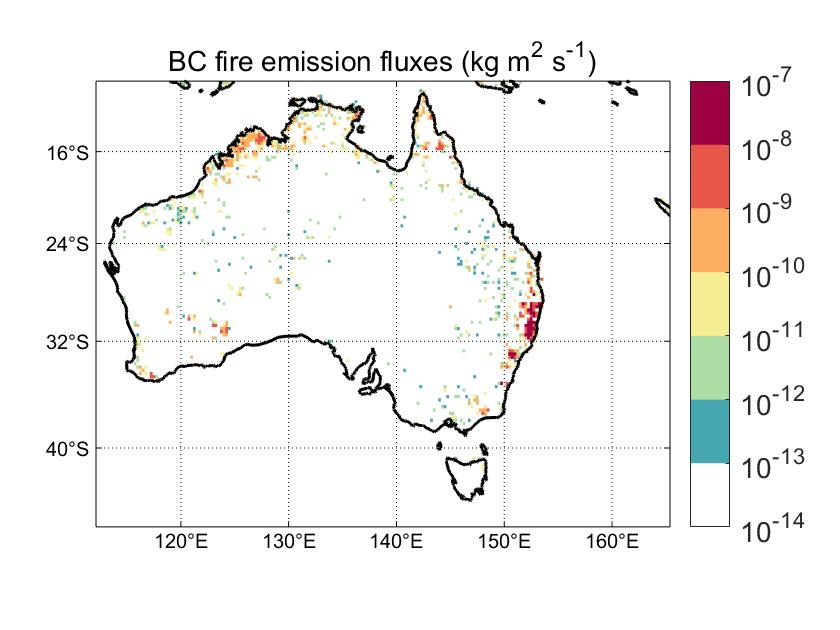

% fire emissions
var1 = squeeze(nansum(gfed_var(:,:,:,1),3));
figure1 = figure;
m_proj('mercator','lon',[min(lon),max(lon)],'lat',[min(lat),max(lat)]);
m_pcolor(lon,lat,log10(var1'));
hold on;
m_grid
m_plotbndry('C:\Program Files\MATLAB\R2017b\m_map\world','color','k','linewidth',1.5);
shading flat
hold on
climax = -7;
climin = -14;
set(gca,'clim',[climin,climax]);
color_map = flipud(othercolor('Spectral10',7));
color_map(1,:) = 1;
colormap(color_map);
hcol = colorbar;
set(hcol,'FontSize',14);
set(hcol,'TickLabels',{'10^-^1^4','10^-^1^3','10^-^1^2','10^-^1^1','10^-^1^0','10^-^9','10^-^8','10^-^7'});
title('BC fire emission fluxes (kg m^2 s^-^1)','FontSize',14)

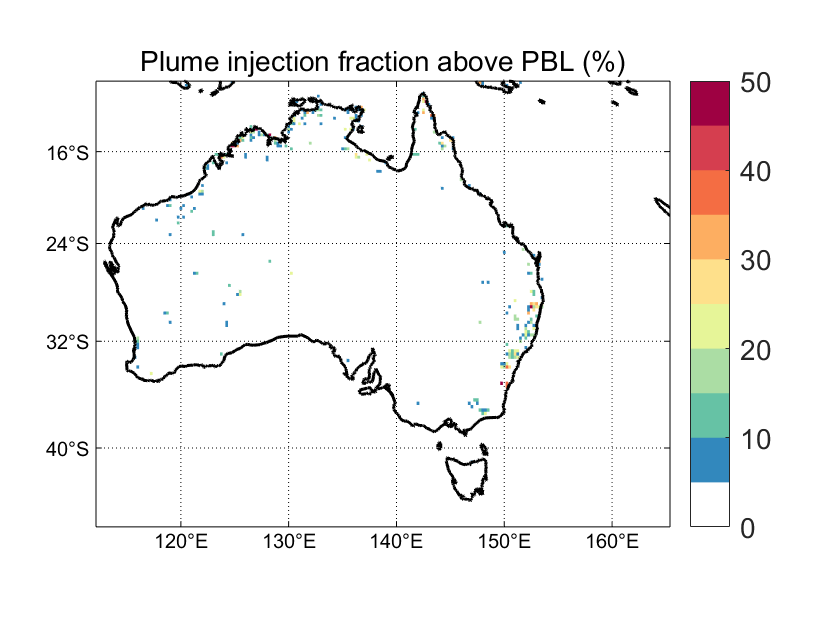


% plume injection fractions
var2 = squeeze(mean(ratio_all(:,:,tt_indx1:tt_indx2),3));
figure2 = figure;
m_proj('mercator','lon',[min(lon),max(lon)],'lat',[min(lat),max(lat)]);
m_pcolor(lon,lat,var2'*100);
m_grid
m_plotbndry('C:\Program Files\MATLAB\R2017b\m_map\world','color','k','linewidth',1.5);
shading flat
hold on
climax = 50;
climin = 0;
set(gca,'clim',[climin,climax]);
color_map = flipud(othercolor('Spectral10',10));
color_map(1,:) = 1;
colormap(color_map);
hcol = colorbar;
set(hcol,'FontSize',14);
title('Plume injection fraction above PBL (%)','FontSize',14);

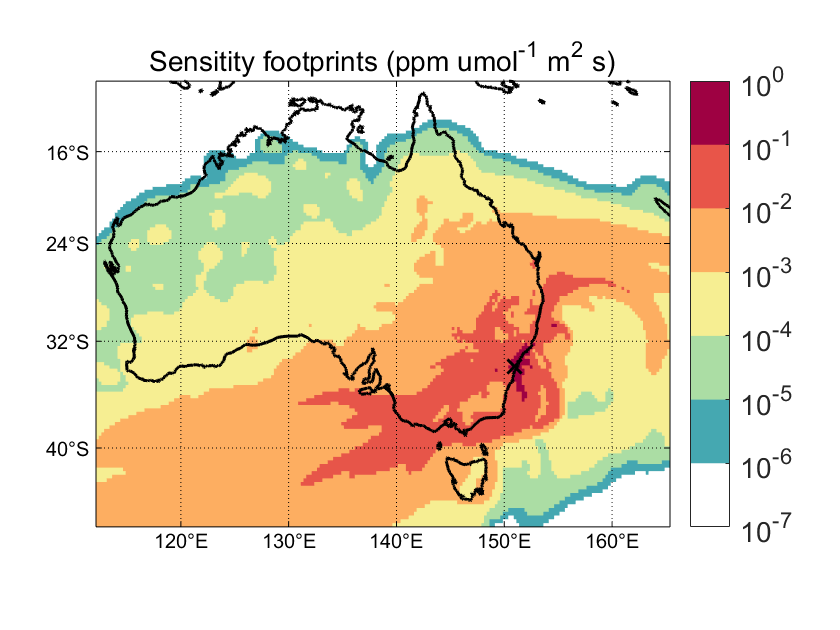


% Sensitivity footprint
var3 = squeeze(nansum(footprint_mean(:,:,:,irec),3));
figure3 = figure;
m_proj('mercator','lon',[min(lon),max(lon)],'lat',[min(lat),max(lat)]);
m_pcolor(lon,lat,log10(var3'));
hold on;
m_plot(loc_lon(irec),loc_lat(irec),'kx','linewidth',1.5,'MarkerSize',10);
m_grid
m_plotbndry('C:\Program Files\MATLAB\R2017b\m_map\world','color','k','linewidth',1.5);
shading flat
hold on
climax = 0;
climin = -7;
set(gca,'clim',[climin,climax]);
color_map = flipud(othercolor('Spectral10',7));
color_map(1,:) = 1;
colormap(color_map);
hcol = colorbar;
set(hcol,'FontSize',14);
set(hcol,'TickLabels',{'10^-^7','10^-^6','10^-^5','10^-^4','10^-^3','10^-^2','10^-^1','10^0'});
title('Sensitity footprints (ppm umol^-^1 m^2 s)','FontSize',14);

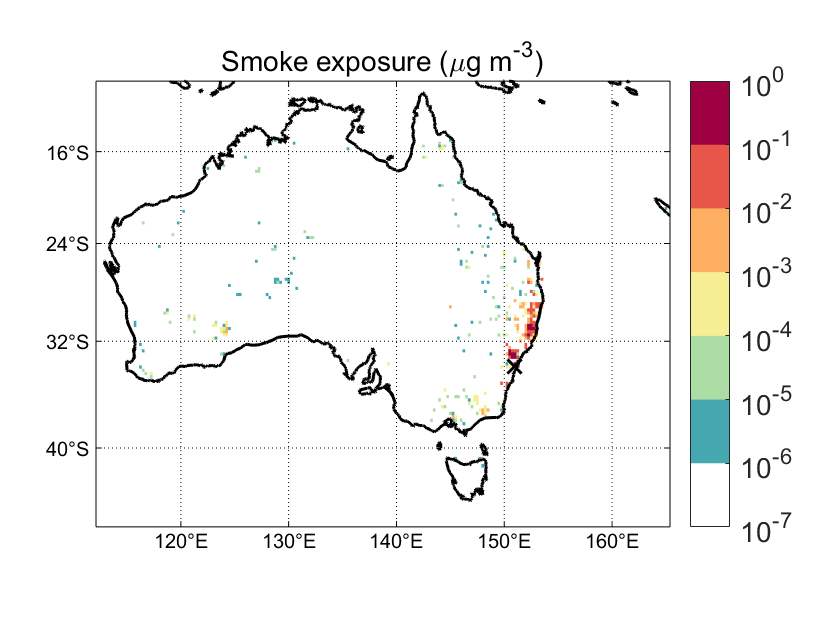


var4 = squeeze(nansum(smoke_exp4(:,:,:,irec,1),3));
figure4 = figure;
m_proj('mercator','lon',[min(lon),max(lon)],'lat',[min(lat),max(lat)]);
m_pcolor(lon,lat,log10(var4'));
hold on;
m_plot(loc_lon(irec),loc_lat(irec),'kx','linewidth',1.5,'MarkerSize',10);
m_grid
m_plotbndry('C:\Program Files\MATLAB\R2017b\m_map\world','color','k','linewidth',1.5);
shading flat
hold on
climax = 0;
climin = -7;
set(gca,'clim',[climin,climax]);
color_map = flipud(othercolor('Spectral10',7));
color_map(1,:) = 1;
colormap(color_map);
hcol = colorbar;
set(hcol,'FontSize',14);
set(hcol,'TickLabels',{'10^-^7','10^-^6','10^-^5','10^-^4','10^-^3','10^-^2','10^-^1','10^0'});
title('Smoke exposure (\mug m^-^3)','FontSize',14);